img = imread('/Users/zrp/Desktop/zrpstudy/program/DIPHW/IMG_1701.JPG')

img = 4640×6960×3 uint8 数组
img(:,:,1) =

  列 1 至 1,666

   187   189   188   186   189   193   191   185   195   194   192   191   188   188   193   199   195   200   199   196   195   191   186   187   190   198   201   207   206   203   206   207   207   205   204   205   203   202   199   199   198   201   200   196   197   204   205   201   193   197   205   208   203   193   195   201   202   201   200   198   195   194   197   202   200   196   196   200   198   196   195   198   204   205   203   199   200   196   194   193   198   203   202   203   204   198   196   205   204   202   204   202   199   201   206   205   200   199   198   202   204   203   203   203   199   198   202   205   205   202   206   210   209   209   208   209   210   212   208   204   201   207   216   219   214   208   206   204   204   201   198   201   205   205   205   205   206   206   204   202   202   205   208   212   207   205   201   201   204   205   202   206   207   207   206   203   203  

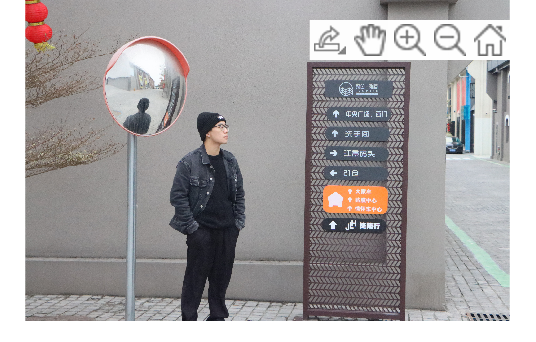

imshow(img)

img = imcrop(img,[0 0 1000 1000])

img = 1000×1000×3 uint8 数组
img(:,:,1) =

   187   189   188   186   189   193   191   185   195   194   192   191   188   188   193   199   195   200   199   196   195   191   186   187   190   198   201   207   206   203   206   207   207   205   204   205   203   202   199   199   198   201   200   196   197   204   205   201   193   197   205   208   203   193   195   201   202   201   200   198   195   194   197   202   200   196   196   200   198   196   195   198   204   205   203   199   200   196   194   193   198   203   202   203   204   198   196   205   204   202   204   202   199   201   206   205   200   199   198   202   204   203   203   203   199   198   202   205   205   202   206   210   209   209   208   209   210   212   208   204   201   207   216   219   214   208   206   204   204   201   198   201   205   205   205   205   206   206   204   202   202   205   208   212   207   205   201   201   204   205   202   206   207   207   206   203   203   205   205   20

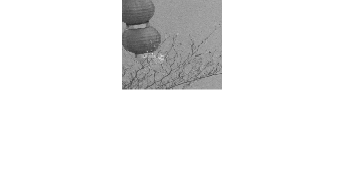

img = rgb2gray(img);
img = imresize(img,0.1,'nearest');
imshow(img)
title('Original Image');

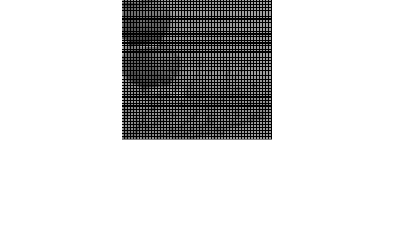

scale = 1.5;
new_width = round(size(img, 2) * scale);
new_height = round(size(img, 1) * scale);
new_img = zeros(new_height, new_width);

for i = 1:new_height
    for j = 1:new_width
        % 计算原图像中对应的位置
        x = j / scale;
        y = i / scale;
        
        % 取整得到四个最近的像素位置
        x1 = floor(x);
        x2 = ceil(x);
        y1 = floor(y);
        y2 = ceil(y);
        if x1 < 1
            x1 = x1 + 1;
            x2 = x2 + 1;
        end
        if y1 < 1
            y1 = y1 + 1;
            y2 = y2 + 1;
        end
        % 计算四个最近像素的权重
        f1 = (x - x1)/(x2 - x1)* img(x1,y1) + (x2 - x)/(x2 - x1) * img(x2,y1);
        f2 = (x - x1)/(x2 - x1)* img(x1,y2) + (x2 - x)/(x2 - x1) * img(x2,y2);
        new_img(j,i) = (y - y1)/(y2 - y1)*f1 + (y2 - y)/(y2 - y1) * f2;
    end
end
% 显示新图像
figure, imshow(uint8(new_img));title('Bilinear Interpolated Image');